#                                                                      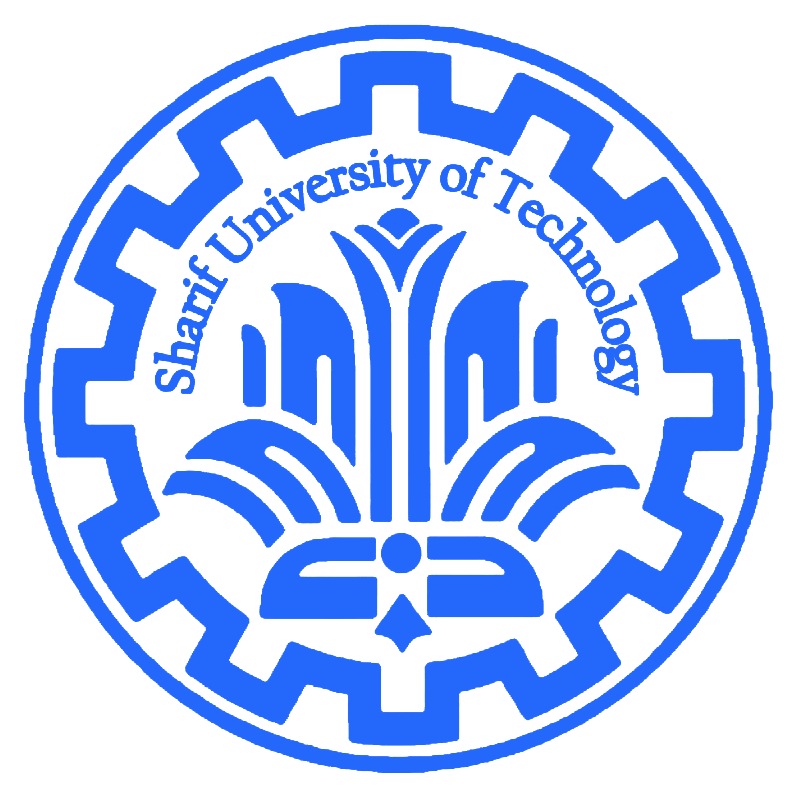

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#3
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#2}$$


**............................................................................................................**

### 
$$\text{Part B}.$$
 

.............................................................................................................

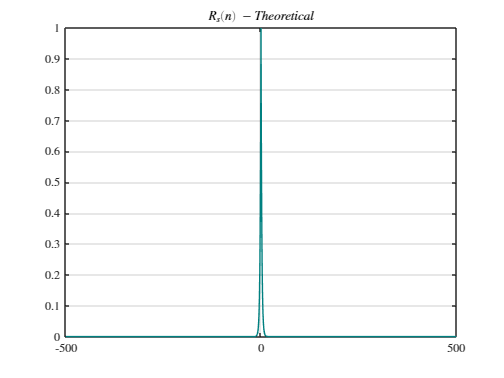

N = 1000;
n = -N/2:1:N/2;
R_s = (0.6).^n.*step_function(n-1) + (0.6).^(-n).*step_function(-n);

figure
plot(n,R_s,'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$R_s(n)\;-\;Theoretical$','interpreter','latex')
grid on;

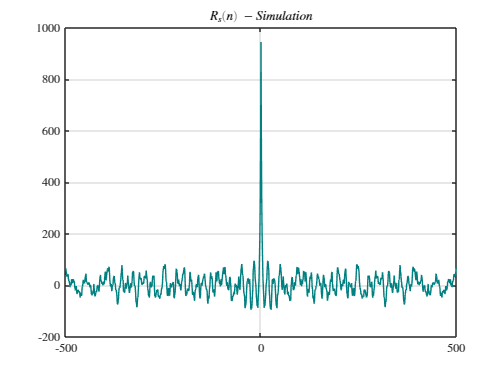

s = zeros(1,1);
v = 0.8*randn(1,N);
for i = 2:N
    s(1,i) = 0.6*s(1,i-1) + v(i);
end

[R_s_sim,lags] = xcorr(s,s,500);
figure
plot(lags,R_s_sim,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$R_s(n)\;-\;Simulation$','interpreter','latex')
grid on;

n = 0:1:N/2;
R_s = (0.6).^n.*step_function(n-1) + (0.6).^(-n).*step_function(-n);
w = 0.8*randn(1,N);
x = s + w;

### 
$$\text{Part C}.$$
 

.............................................................................................................

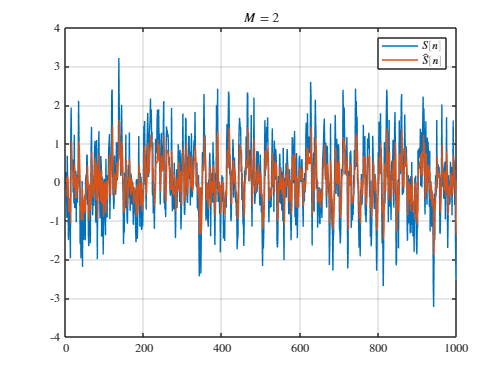

M = 2;
R_w = [1,zeros(1,M-1)];
R_upper = zeros(M,M);
for i = M:-1:1
    R_upper(i,i:M) = R_s(1,1:M-i+1) + R_w(1,1:M-i+1);
end
R = tril(R_upper') + triu(R_upper, 1);
h = inv(R)*(R_s(1,1:M))';

s_hat_2 = zeros(size(s));
for i=1:M
    s_hat_2(1,:) = s_hat_2(1,:) + h(i)*[zeros(1,i),s(1,1:N-i)];
end

figure
plot(s)
hold on
plot(s_hat_2)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$M = 2$','interpreter','latex')
legend('$S[n]$','$\hat{S}[n]$','interpreter','latex')
grid on;

### 
$$\text{Part D}.$$
 

.............................................................................................................

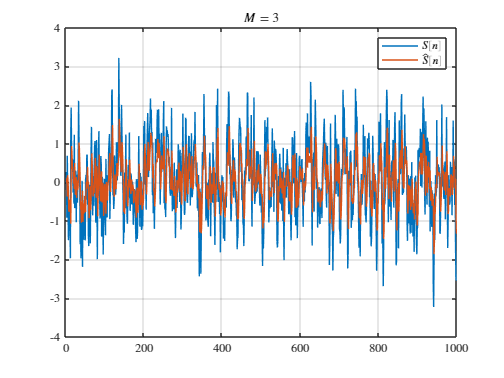

M = 3;
R_w = [1,zeros(1,M-1)];
R_upper = zeros(M,M);
for i = M:-1:1
    R_upper(i,i:M) = R_s(1,1:M-i+1) + R_w(1,1:M-i+1);
end
R = tril(R_upper') + triu(R_upper, 1);
h = inv(R)*(R_s(1,1:M))';

s_hat_3 = zeros(size(s));
for i=1:M
    s_hat_3(1,:) = s_hat_3(1,:) + h(i)*[zeros(1,i),s(1,1:N-i)];
end

figure
plot(s)
hold on
plot(s_hat_3)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$M = 3$','interpreter','latex')
legend('$S[n]$','$\hat{S}[n]$','interpreter','latex')
grid on;

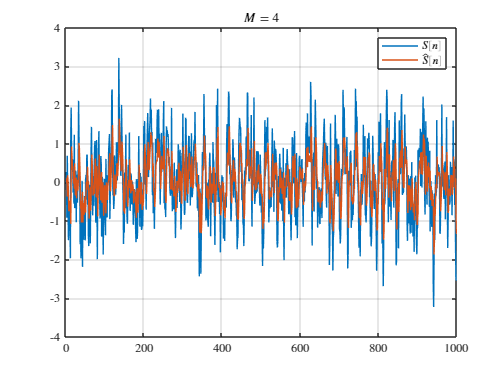

M = 4;
R_w = [1,zeros(1,M-1)];
R_upper = zeros(M,M);
for i = M:-1:1
    R_upper(i,i:M) = R_s(1,1:M-i+1) + R_w(1,1:M-i+1);
end
R = tril(R_upper') + triu(R_upper, 1);
h = inv(R)*(R_s(1,1:M))';

s_hat_4 = zeros(size(s));
for i=1:M
    s_hat_4(1,:) = s_hat_4(1,:) + h(i)*[zeros(1,i),s(1,1:N-i)];
end

figure
plot(s)
hold on
plot(s_hat_4)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$M = 4$','interpreter','latex')
legend('$S[n]$','$\hat{S}[n]$','interpreter','latex')
grid on;

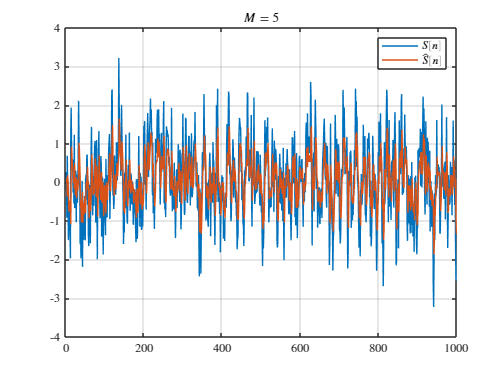

M = 5;
R_w = [1,zeros(1,M-1)];
R_upper = zeros(M,M);
for i = M:-1:1
    R_upper(i,i:M) = R_s(1,1:M-i+1) + R_w(1,1:M-i+1);
end
R = tril(R_upper') + triu(R_upper, 1);
h = inv(R)*(R_s(1,1:M))';

s_hat_5 = zeros(size(s));
for i=1:M
    s_hat_5(1,:) = s_hat_5(1,:) + h(i)*[zeros(1,i),s(1,1:N-i)];
end

figure
plot(s)
hold on
plot(s_hat_5)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$M = 5$','interpreter','latex')
legend('$S[n]$','$\hat{S}[n]$','interpreter','latex')
grid on;

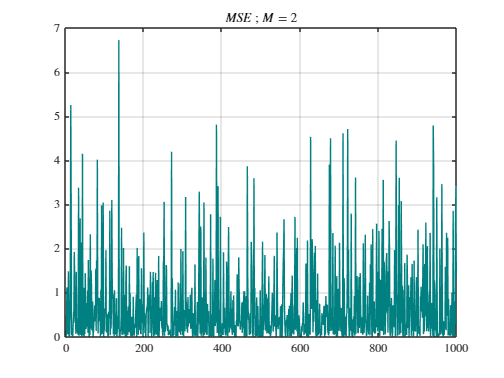

figure
error_2 = (s-s_hat_2).^2;
plot(error_2,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$MSE\;;\;M = 2$','interpreter','latex')
grid on;

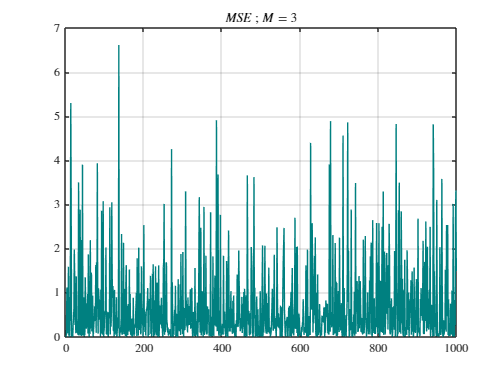

figure
error_3 = (s-s_hat_3).^2;
plot(error_3,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$MSE\;;\;M = 3$','interpreter','latex')
grid on;

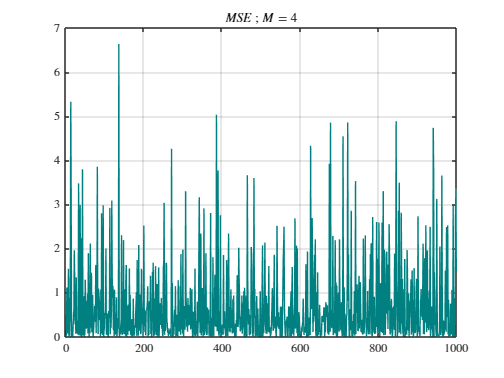

figure
error_4 = (s-s_hat_4).^2;
plot(error_4,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$MSE\;;\;M = 4$','interpreter','latex')
grid on;

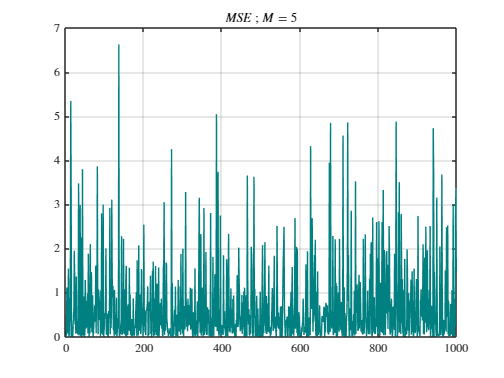

figure
error_5 = (s-s_hat_5).^2;
plot(error_5,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$MSE\;;\;M = 5$','interpreter','latex')
grid on;